# Exercise 3: Optimize electric vehicle (EV) energy consumption with smart charging

## 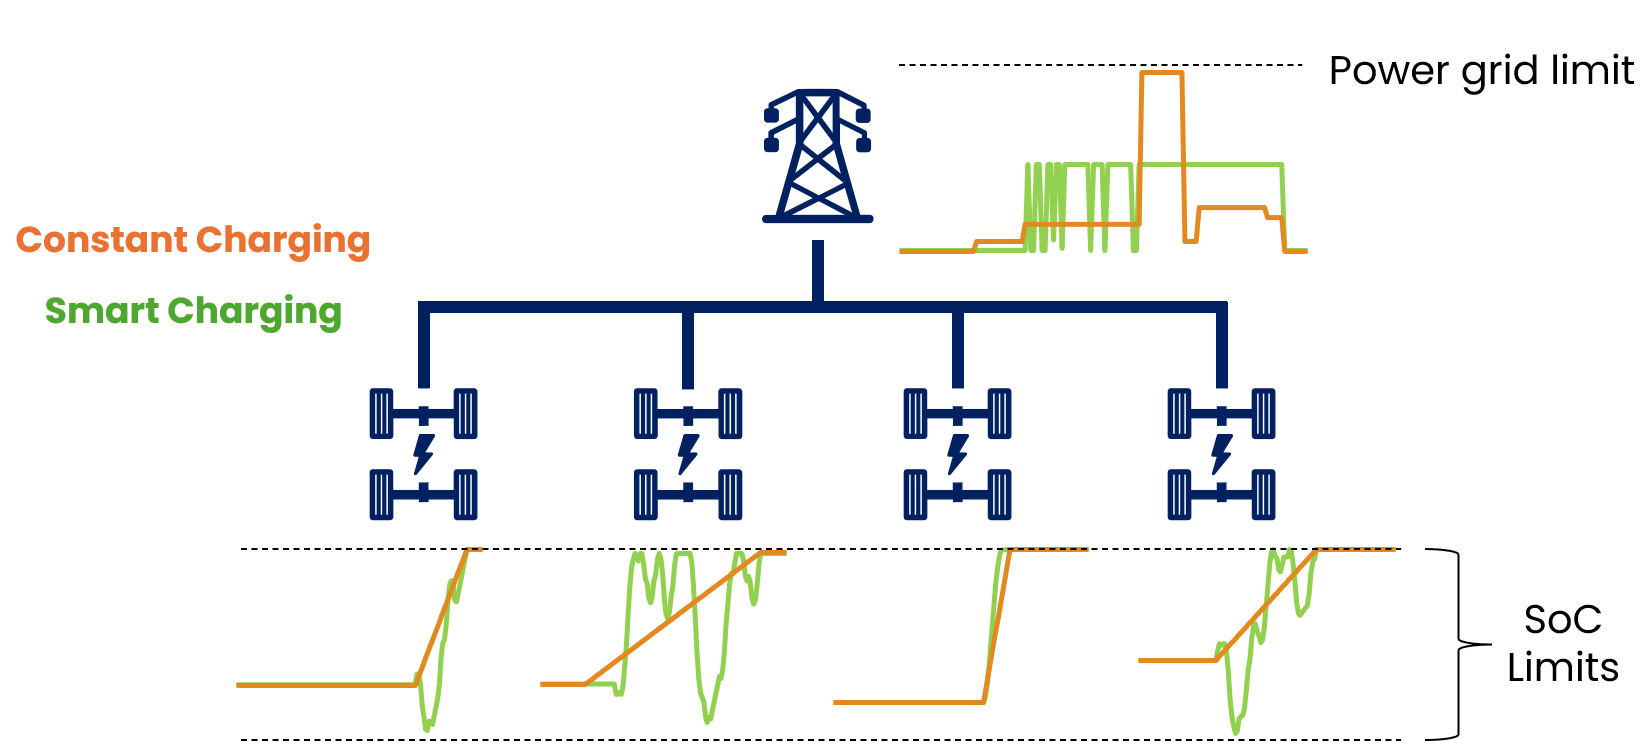

## Define your EV charging scenario

% EV variables:
numEVs = 30;  % Number of EVs
finalSoC = 70; % Desired final battery state of charge (%). Assumption: battery capacity = 80kWh

% Maximum amount of power supported by the grid (kW)
gridUpperLimit = 40;

% Support vehicle-to-grid (V2G) charging
sellingBack = true; % If checked, EV can discharge to the grid to support reliability

## Prepare and visualize input data for electricity prices, demand profile, and EV plug-in times

Load the following input data:

- Electricity prices (buy): cost of consuming electricity from the grid.

- Electricity prices (sell): price for selling electricity back to the grid, assumed to be a fraction of the buying cost.

- Demand profile: electricity consumption for the area without EV demand.

We will assume known start and stop plug-in times, which will be randomly generated.

Our simulation will cover a 24h period and uses a 10min time step. The data for electricity prices and demand is synthesized and mimics real-world behavior.

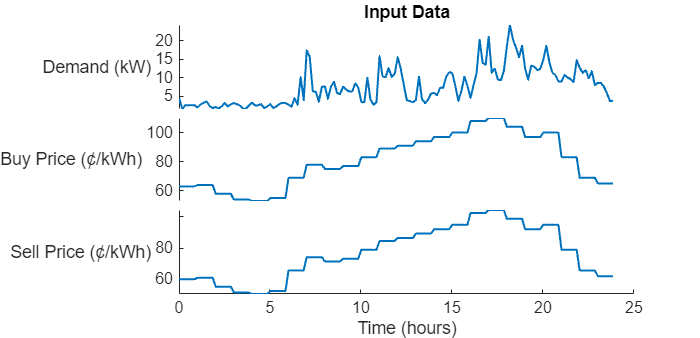

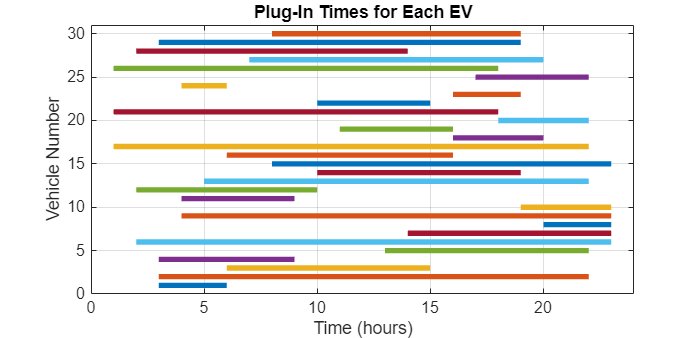

% Load electricity prices and demand profile data
load electricityPrices.mat 
load demandProfile.mat

% Time steps for simulation
numSteps = length(demandProfile);
scalingFactor = numSteps/24; % Scaling factor for converting hours to time-step increment in minutes
minStep = 24*60/numSteps; % Simulation time step in minutes
hourlyStep = (1:minStep:minStep*numSteps)/60;

% Generate start/stop times and charge vectors
[startStopTimes, isPluggedIn] = helper.generateStartStopTimes(scalingFactor, numSteps, numEVs);
[initialCharge, finalCharge]  = helper.generateSoC(numEVs,finalSoC);

% Visualize input data
helper.visualizeInputData(hourlyStep,demandProfile,priceBuy,priceSell,startStopTimes,scalingFactor,numEVs);

## Formulate and solve optimization problem

% Create optimization problem object
prob = optimproblem("ObjectiveSense","min");

% Add problem constraints
prob = helper.defineProblemConstraints(prob,numSteps,numEVs,startStopTimes,scalingFactor,initialCharge,finalCharge,demandProfile,gridUpperLimit,sellingBack);

% Add optimization objective
totalCost = prob.Variables.gridPowerBuy'*priceBuy - prob.Variables.gridPowerSell'*priceSell;
prob.Objective = totalCost;

% Solve optimization problem
optintlin = optimoptions('intlinprog','Display','none');
[sol,fval,exitflag,output] = solve(prob,"Options",optintlin);

## Verify and visualize optimization results

% Verify if a feasible solution was found
isFeasible = helper.verifyResults(sol.evBatteryPower);

### Smart charging profile for each EV

- SoC remains within minimum and maximum limits (red dotted lines).

- SoC for each EV will reach desired final value at the end of their plug-in time (upper black dotted line).

- If vehicle-to-grid discharging is enabled, some EVs might see a drop in SoC.

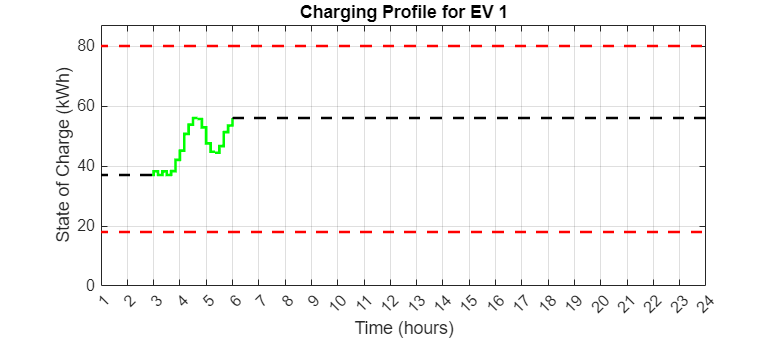

% Select individual EV to visualize state of charge over time
selectedEV = 1; 
helper.visualizeResults(isFeasible,"EV",sol.evBatteryPower, selectedEV, startStopTimes, scalingFactor, initialCharge);

### System-level electricity demand

- Smart charging solution can help prevent grid overload.

- In some instances, using smart charging leads to a feasible solution while constant charging would have been infeasible.

- When vehicle-to-grid discharging is enabled, smart charging solution can become negative, indicating that electricity is being sold back to the grid. 

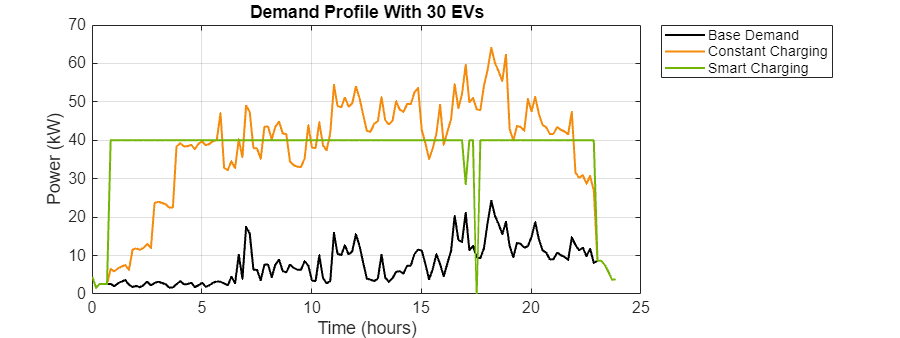

% Find the constant charging rate that each EV would need to achieve the final charge
% expected within the plugged in time
constantChargingRates = scalingFactor*(finalCharge-initialCharge)./(startStopTimes(:,2)-startStopTimes(:,1)+1);
constantProfile = zeros(numSteps,numEVs);
constantProfile(isPluggedIn) = repelem(constantChargingRates, sum(isPluggedIn, 1));

helper.visualizeResults(isFeasible,"System",sol.evBatteryPower, hourlyStep, demandProfile, constantProfile, numEVs);

## References

Here are some suggested references for you to keep exploring this topic:

- [Problem-Based Optimization Workflow](https://www.mathworks.com/help/optim/ug/problem-based-workflow.html) (steps to formulate an optimization problem) 

- [Optimal Dispatch of Power Generators](https://www.mathworks.com/help/optim/ug/optimal-dispatch-problem-based.html) (power grid optimization example)

- [Techno-Economic Analysis of the Impact of EV Charging on the Power Grid](https://www.mathworks.com/videos/techno-economic-analysis-of-the-impact-of-ev-charging-on-the-power-grid-1683546747924.html) (MathWorks webinar) 